
clear;

csvFolderName = "StockVibro";
clockTimeLimit = 2.1; % 体験時間 (s)
stopTime = clockTimeLimit;
stopTable = table(stopTime);
writetable(stopTable, csvFolderName + '\' + "stop.csv");

Stock Left

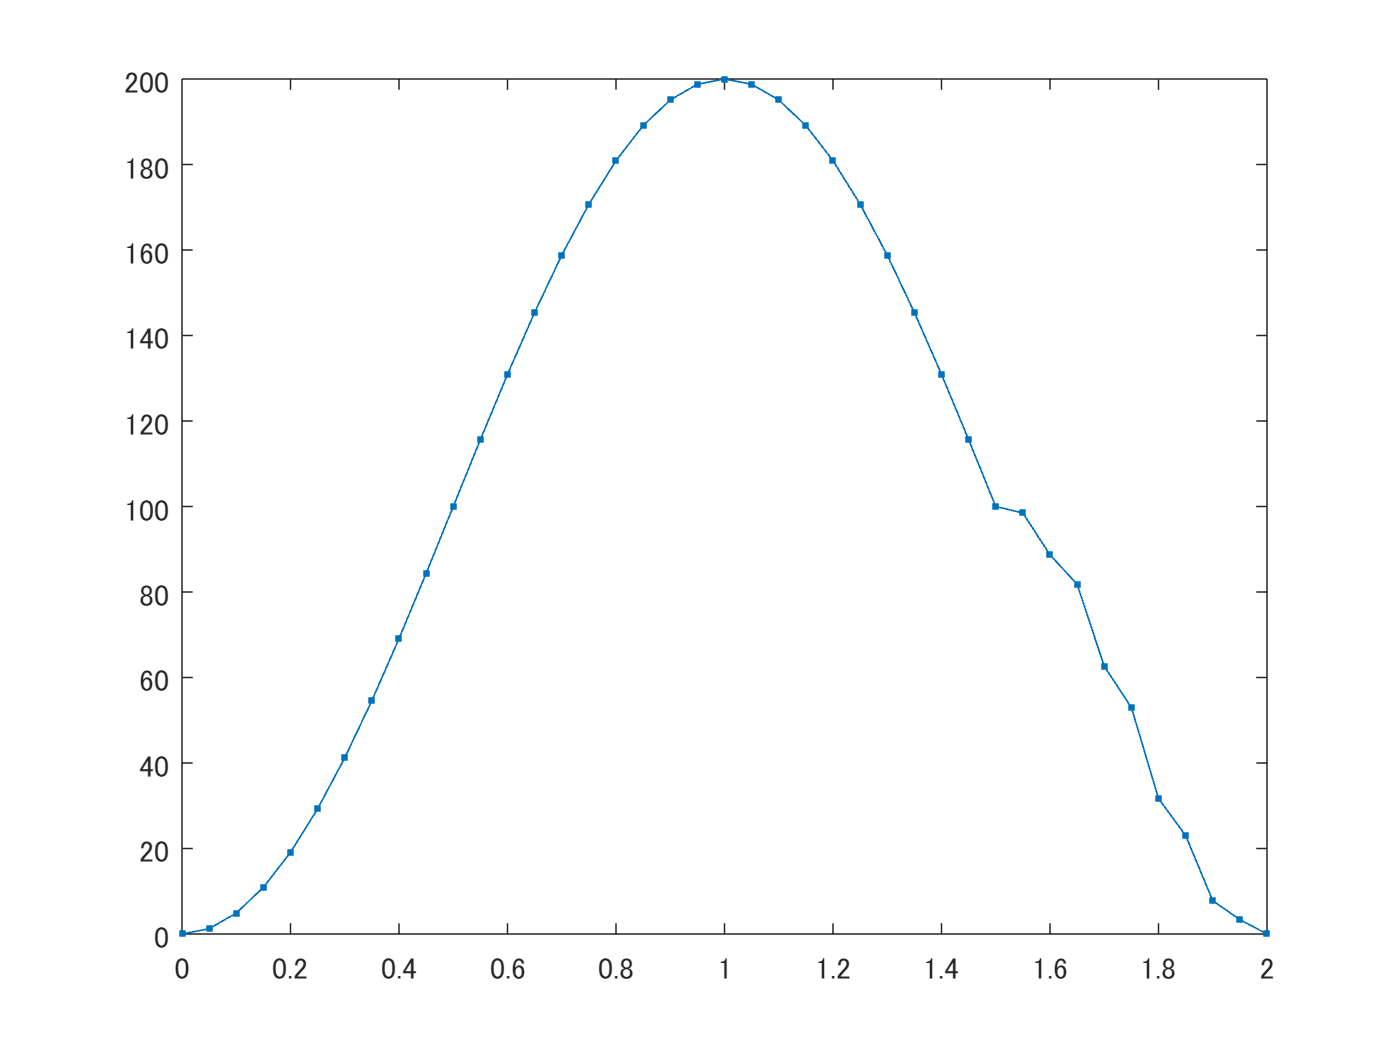

dt = 0.05;
T = 2;
xLimit = 200; % 単位 (mm)
clockTime = (0:dt:T)';

upDurationRatio = 2;
downDurationRatio = 1;
dragDurationRatio = 1;

upDurationRate = upDurationRatio/(upDurationRatio + downDurationRatio + dragDurationRatio);
downDurationRate = downDurationRatio/(upDurationRatio + downDurationRatio + dragDurationRatio);
dragDurationRate = dragDurationRatio/(upDurationRatio + downDurationRatio + dragDurationRatio);

F = 9; % 振動周波数 Hz
Amp = 3; % 振動振幅 mm
% Amp*rand(size((0:dt:3*T/4)'));

x = [
    xLimit * (cos(pi*(0:dt:T*upDurationRate-dt)'/(T*upDurationRate) + pi) + 1)*0.5;
    xLimit * (cos((pi/2)*(0:dt:T*downDurationRate-dt)'/(T*downDurationRate)) + 1)*0.5;
    xLimit/2 * (cos(pi*(0:dt:T*dragDurationRate)'/(T*dragDurationRate)) + 1)*0.5 + Amp*sin(2*pi*F*(0:dt:T*dragDurationRate)');
    ];
figure;
plot(clockTime, x, '.-');

StockVibroCSV = table(clockTime, x)

StockVibroCSV = 41×2 table
    clockTime      x   
    _________    ______

         0            0
      0.05       1.2312
       0.1       4.8943
      0.15       10.899
       0.2       19.098
      0.25       29.289
       0.3       41.221
      0.35       54.601
       0.4       69.098
      0.45       84.357
       0.5          100
      0.55       115.64
       0.6        130.9
      0.65        145.4
       0.7       158.78
      0.75       170.71


writetable(StockVibroCSV, csvFolderName + '\' + "StockVibro.csv");

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end